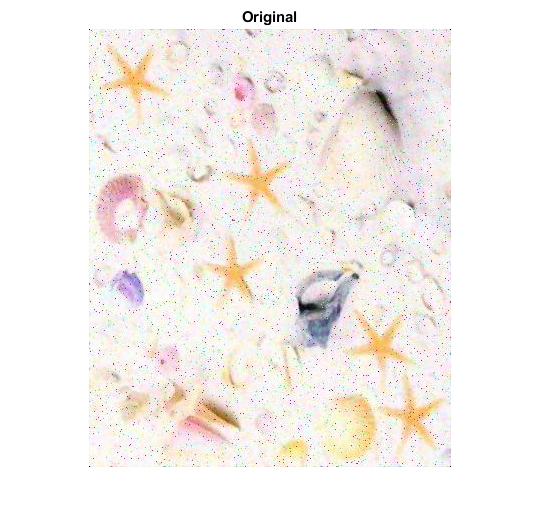

oim = imread("images\starfish_noise3.jpg");
imshow(oim)
title("Original");

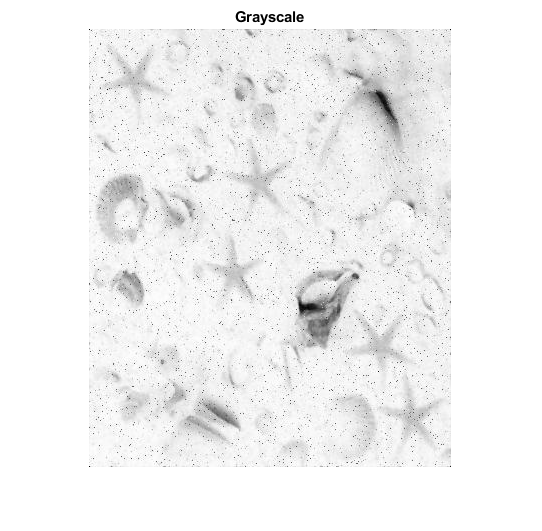


im= oim;
im = rgb2gray(oim);
imshow(im)
title("Grayscale");

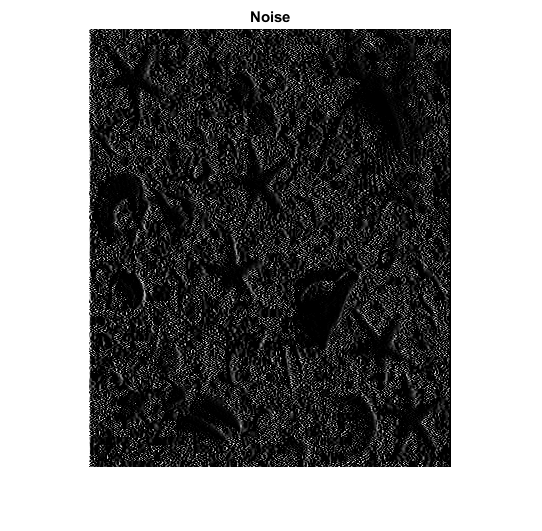


% im = medfilt2(im, [5 5]);
% im = imgaussfilt(im, 2);
% imshow(im)
% 
% im = imsharpen(im, 'amount',5);
% imshow(im)

% Detect noise
noise = histeq(im);
noise = imfilter(noise, [-1 0 1;]);
imshow(noise)
title("Noise");

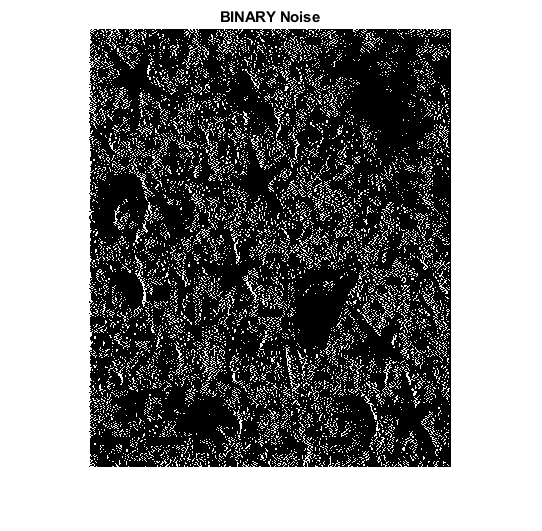

level = graythresh(noise);
noise = imbinarize(noise,level);
imshow(noise)
title("BINARY Noise");

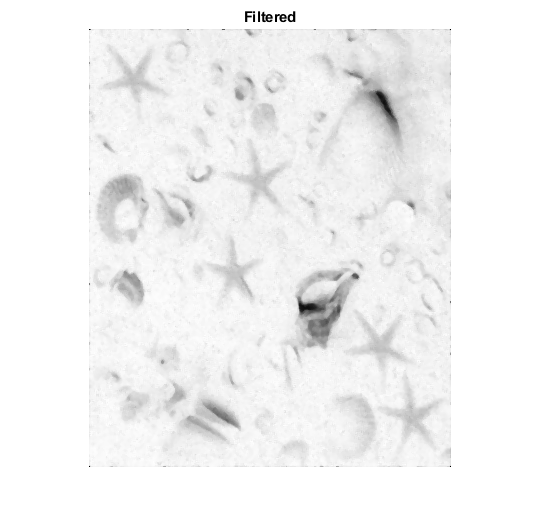

noise = find(~noise == 1); % Shows salt and pepper!

% Create smoothed version of image
filtered = medfilt2(im, [3 3]);
imshow(filtered)
title("Filtered");

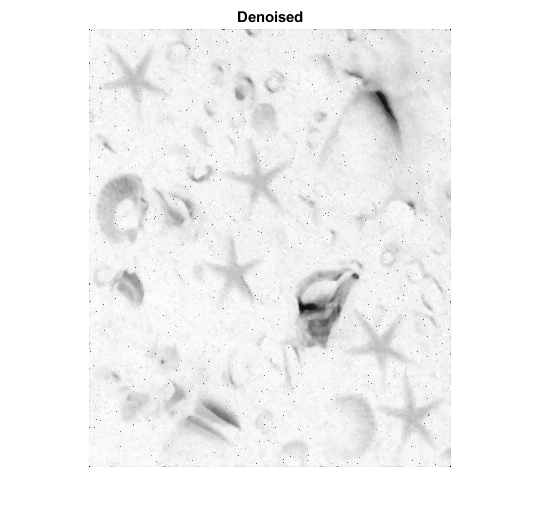


% Swap noisy pixels for filtered ones
denoised = im;
denoised(noise) = filtered(noise);
imshow(denoised)
title("Denoised");

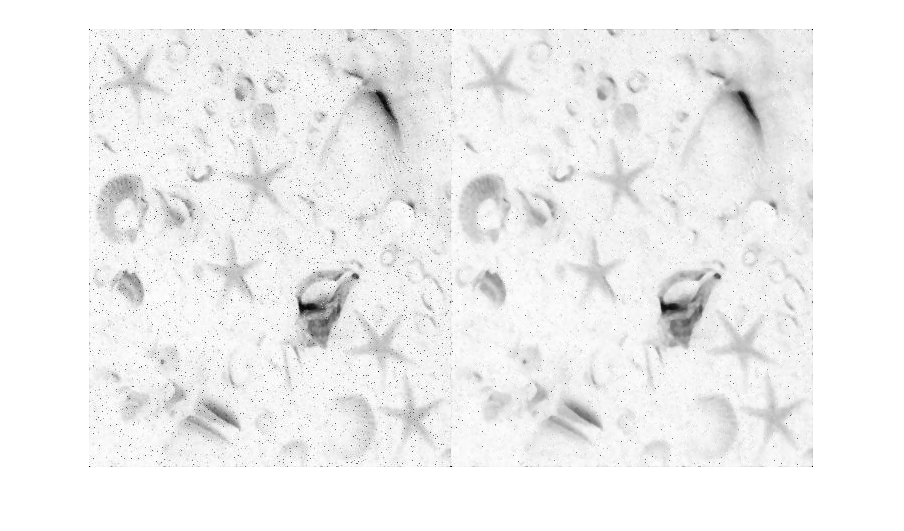


im = rgb2gray(oim);
imshowpair(im, denoised, 'montage')

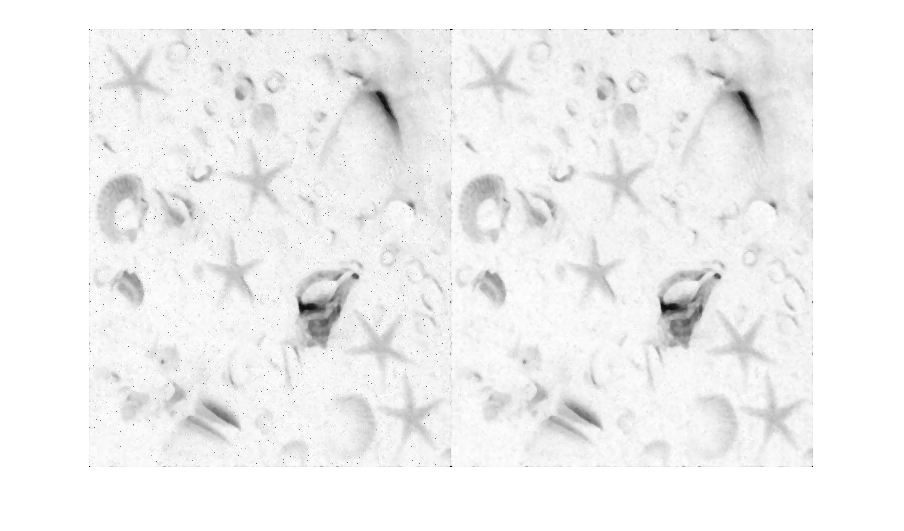

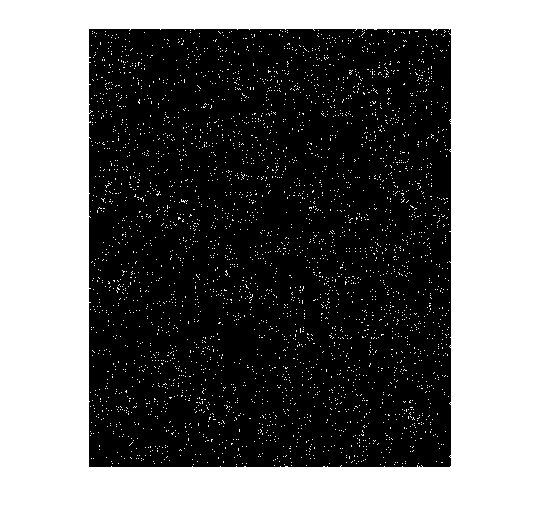

imshowpair(denoised, filtered, 'montage')

function imP = DenoiseSP(im)

dims = ndims(im);

if (dims == 2)
    imP = DenoiseSP2D(im);
elseif (dims == 3)
    imP = DenoiseSP3D(im);
else
    error("Unsupported number of dimensions. Expected a 2D or 3D array.");
end
end

function noise = GetSPNoise(im)
    m = mean2(im);
    s = std2(im);
    pl = max(m + s, 255); % Mean + std deviation OR 255.
    mi = max(m - s, 0); % Mean - std deviation OR 0.

% Find possible impulse noise (where pixels = 0 or 255).
% noise = (im == 0 | im == 255);
    noise = (im <= mi| im >= pl); % Smoother but still noise and shadow loss.
%     noise = (im == min(im)| im == max(im));

% Output % of "noisy" pixels in the image.
%     [i j] = find(im == 0| im == 255);
%     nImPx = numel(im) / 2;
%     nNoisyPx = length(i);
%     percentNoise = (100/ nImPx) * nNoisyPx;
%     disp("S&P Noise: " + percentNoise + "%")
end

function imP = DenoiseSP2D(im)
noise = GetSPNoise(im);

% Create a median filtered copy of im.
filtered = medfilt2(im, [5 5]);

% Swap noisy pixels with filtered pixels.
denoised = im;
denoised(noise) = filtered(noise);

imP = denoised;

%     Consideration...
%     Conditionally determine filter size based on numel(noise).
end

function imP = DenoiseSP3D(im)
% Separate image channels.
[ch1, ch2, ch3] = imsplit(im);

% Denoise channels individually.
dnCh1 = DenoiseSP2D(ch1);
dnCh2 = DenoiseSP2D(ch2);
dnCh3 = DenoiseSP2D(ch3);

% Concatenate channels to create noise free image.
imP = cat(3, dnCh1, dnCh2, dnCh3);
end